## Setup

% Test Script for plotCR3BPOrbit Function

% Clear workspace and figures
clear; close all; clc;

% Define CR3BP Parameters
Lpoints = [
    0.8369,  0.0;       % L1
    1.1557,  0.0;       % L2
    0,  0;              % L3
    0,  0;              % L4
    0,  0;              % L5
];

mu = 0.012150585609624;   % Gravitational parameter for Earth-Moon system
n = 1;                    % Mean motion (normalized units)
       
%% Define ODE Solver Options
optionsODE = odeset('RelTol',1e-13, 'AbsTol',1e-13);


### XAI Paper Orbits 

% NHL1s
    NHL1_1 = [0.8233798414, 0, 0.0172411539, 0, 0.1311291036, 0, 2.7450127781];
    NHL1_2 = [0.8801260326, 0, 0.1933262300, 0, 0.2235236647, 0, 2.1260109107];
    NHL1_3 = [0.9334801983, 0, 0.2497318810, 0, 0.0892287702, 0, 1.9359832911];    
    NHL1s = [NHL1_1 ; NHL1_2; NHL1_3];

   % Choose orbit initial condition to plot  
   IC = NHL1_1

IC =       0.82338            0     0.017241            0      0.13113            0        2.745


## Plotting Test Cases 

### Test Case 1: Plot Orbits Colored by Jacobi Constant (Flag = 1)

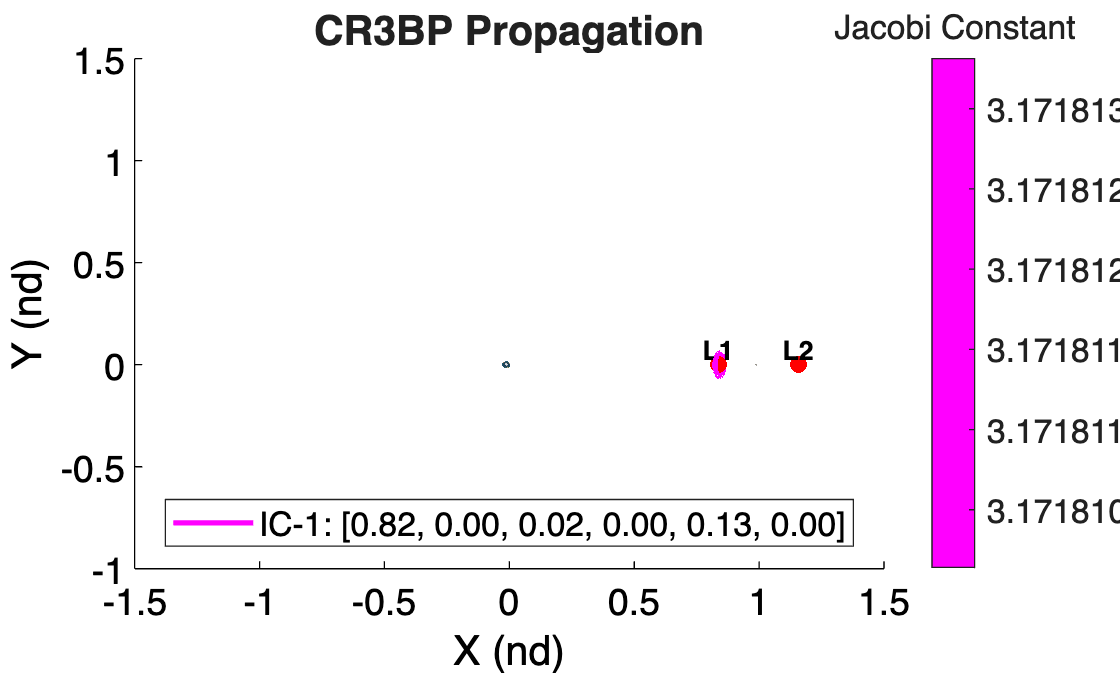

    Flag = 1;  % Jacobi Constant Coloring
    figure('Name', 'Orbits Colored by Jacobi Constant');    
    plotCR3BPOrbit(NHL1_1, Lpoints, mu, n, optionsODE, Flag);

### Test Case 2: Plot Orbits Colored by Period (Flag = 2) and Black Background

    % Flag = 0;   
    % figure('Name', 'Orbits Colored by Period');
    % plotCR3BPOrbit(IC, Lpoints, mu, n, optionsODE, Flag, 'blackBackground', true, 'LineWidth', 3, 'color', 'g');
    % title('CR3BP Orbits Colored by Period');

### Test Case 3: Plot Orbits with Custom Color and Line Properties

    % Flag = 0;  
    % figure('Name', 'Orbits with Custom Color and Line Properties')
    % plotCR3BPOrbit(IC, Lpoints, mu, n, optionsODE, Flag, 'color', [0, 0.5, 0], 'LineWidth', 2, ...
    %     'LineStyle', '--', 'plotRealisticPrimaries', true, 'showLegends', false);               
    % title('CR3BP Orbits with Custom Color and Line Properties'); 

### Test Case 4: Plot Orbits with Initial Velocity Arrows

    % Flag = 0;  
    % figure('Name', 'Orbits with Initial Velocity Arrows');
    % plotCR3BPOrbit(IC, Lpoints, mu, n, optionsODE, Flag, ...
    %     'arrows', true, ...                          % Enable velocity arrows
    %     'LineWidth', 1.5, ...                         
    %     'LineStyle', '-');                            
    % title('CR3BP Orbits with Initial Velocity Arrows');

### Test Case 5: Plot Orbits into an Existing Figure

    % % Create an existing figure handle
    % existingFig = figure('Name', 'Existing Figure for CR3BP Orbits');
    % 
    % % Plot orbits into the existing figure
    % plotCR3BPOrbit(IC, Lpoints, mu, n, optionsODE, Flag, ...
    %     'figureHandle', existingFig, ...            
    %     'LineWidth', 1.5, ...                       
    %     'LineStyle', '-');                          
    % title(existingFig.CurrentAxes, 'CR3BP Orbits Plotted into Existing Figure');

## Test Functions Space

function [vu, vs] = computeMonodromyEigenvectors(lib, X0, mu, n, Period)
    % Compute monodromy matrix and eigenvectors for a given initial state
    Xaug0 = [X0; reshape(eye(6), 36, 1)]; % Initial state + STM
    
    % Integrate full period to get monodromy matrix
    [~, Y_aug] = ode45(@(t,X) lib.augmentedDynamicsCR3BP(t,X,mu,n),...
        [0 Period], Xaug0, odeset('RelTol',1e-12));
    
    Phi_T = reshape(Y_aug(end, 7:end), 6, 6); % Extract monodromy matrix
    
    % Eigenanalysis with sorting
    [eVecs, eVals] = eig(Phi_T);
    lambda = diag(eVals);
    
    % Sort by eigenvalue magnitude descending
    [~, idx] = sort(abs(lambda), 'descend');
    lambda = lambda(idx);
    eVecs = eVecs(:,idx);
    
    % Extract unstable (λ > 1) and stable (λ < 1) eigenvectors
    vu = real(eVecs(:,abs(lambda) > 1.1));
    vs = real(eVecs(:,abs(lambda) < 0.9));
end


## Functions 


    function f = plotCR3BPOrbit(ICs, Lpoints, mu, n, optionsODE, Flag, varargin)
        % plotCR3BPOrbit Plots the trajectory for the Circular Restricted Three Body Problem (CR3BP) given initial conditions or precomputed states, marks the libration points, and optionally colors the orbits based on their Jacobi constant values or provided color.
            %  Last Update: 17-04-2024
            % Usage:
            %   f = obj.plotCR3BPOrbit(ICs, Lpoints, mu, n, optionsODE, Flag, varargin)
            %
            % Inputs:
            %   ICs - An initial state vector (col or row) of 7 elements or a matrix where each row contains the state vector and final time for a particular orbit, or precomputed states for direct plotting.
            %   Lpoints - A 5x2 matrix containing the x and y coordinates of the five libration points, L1 through L5. A row should be set to [0, 0] if a particular libration point is not to be plotted.
            %   mu - Gravitational parameter for the CR3BP, representing the mass ratio of the two primary bodies.
            %   n - Mean motion (average angular velocity) in the CR3BP system, typically set to 1 for normalized units.
            %   optionsODE - MATLAB ODE solver options structure, typically created with odeset.
            %   Flag - A boolean flag indicating whether to color the orbits based on their Jacobi Constant (JC) or period values. If 1 JC, if 2 period values.
            %   varargin - Additional optional parameters:
            %       'arrows' - If true, plots direction arrows at the start of each trajectory.
            %       'color' - Specifies a custom color for plotting the orbits.
            %       'states' - If true, treats ICs as precomputed states that are plotted directly.
            %       'figureHandle' - A MATLAB figure handle to plot into an existing figure.
            %       'blackBackground' - True for black image background 
            % Outputs:
            %   f - The figure handle to the generated plot.
            %
            % The function computes the Jacobi constant for each orbit using the provided initial conditions if Flag is set to true. It uses these constants to generate a colormap, which is then used to color the orbits. A colorbar is added to the figure to serve as a scale for the Jacobi constant values. If Flag is false, orbits are plotted in standard colors or using a custom color if specified.
            %
            % The function also adds textured representations of the Earth and the Moon to the plot at their respective positions in the normalized CR3BP frame. Additionally, it plots the provided libration points and labels them accordingly. If the 'states' flag is set, the function directly plots the precomputed states without further integration.
        
            % Create an input parser
            p = inputParser;
        
            % Define default values
            defaultArrows = false;
            defaultFigHandle = [];
            defaultColor = 'b';  
            defaultLineWidth = 2;  
            blackBackground = false;  
            defaultPlotRealisticPrimaries = true; 
            defaultShowLegends = true;             % Default to true

            
            % Add parameters to input parser
            addParameter(p, 'arrows', defaultArrows, @islogical);
            addParameter(p, 'figureHandle', defaultFigHandle, @(x) isempty(x) || (ishandle(x) && strcmp(get(x, 'Type'), 'figure')));
            addParameter(p, 'states', false, @islogical); % Handling 'states' flag
            addParameter(p, 'color', defaultColor, @(x) ischar(x) || (isnumeric(x) && size(x,2) == 3)); % Color input for plotting
            addParameter(p, 'LineWidth', defaultLineWidth, @isnumeric); % Line width input for plotting
            addParameter(p, 'LineStyle', '-', @(x) ischar(x) || (isstring(x) && isscalar(x)));
            addParameter(p, 'blackBackground', blackBackground, @islogical);  % Added 'background' parameter
            addParameter(p, 'plotRealisticPrimaries', defaultPlotRealisticPrimaries, @islogical);                
            addParameter(p, 'showLegends', defaultShowLegends, @islogical);                        


            % Parse input arguments
            parse(p, varargin{:});
        
            % Extract values from the parser
            Arrows = p.Results.arrows;
            figHandle = p.Results.figureHandle;
            plotStatesDirectly = p.Results.states;   % Use directly the parsed result
            plotColor = p.Results.color;             % Extracted color parameter
            LineWidth = p.Results.LineWidth;         % Extracted line width
            LineStyle = p.Results.LineStyle;
            blackBackground = p.Results.blackBackground;  % Extract 'background' parameter
            plotRealisticPrimaries = p.Results.plotRealisticPrimaries;
            showLegends = p.Results.showLegends;                       
        
        % - - - - Preliminary Setup - - - - -               
            t_star = 375704.306539867;                  % [s]
            t_star = t_star/3600;                       % [hrs]
            
            % Load textures if primaries are to be plotted
            if plotRealisticPrimaries
                earthTexture = imread('earth.jpg');
                moonTexture = imread('moon.tif');
            end
        
        % - - - - Sanity Check on the ICs Vector or Matrix Provided - - - - -     
            if ~plotStatesDirectly 
                % Check if ICs is a vector and has exactly 7 elements
                if isvector(ICs) && length(ICs) == 7
                    if iscolumn(ICs)
                        ICs = ICs';                 % Convert column vector to row vector
                    end
                elseif ismatrix(ICs) && size(ICs, 2) == 7
                    % No action needed for matrix with correct format
                else
                    error('ICs must be a 7-element vector or a matrix with 7 columns. Each row represents [x, y, z, vx, vy, vz, Tmax].');
                end
            end 
        
           % Check and clean ICs from NaN rows
            validICs = all(~isnan(ICs), 2);  % Logical index of rows without NaN
            ICs = ICs(validICs, :);          % Remove rows with NaN
        
        % - - - - Figure Initial Setup - - - - -     
        
            if isempty(figHandle)
                f = figure('Visible', 'on');  % Create a new figure if no handle provided
                hold on
            else
                f = figure(figHandle);        % Use the provided figure handle
                hold on;                      % Ensure we're adding to the existing figure
            end
        

        % --- Set the background color based on the 'background' parameter ---            
            % Set background and axis colors
            if blackBackground
                % Set to black background
                set(gca, 'Color', 'k', 'XColor', 'w', 'YColor', 'w', 'ZColor', 'w', 'FontSize', 14);
                set(gcf, 'Color', 'k');
                xlabel('X (nd)', 'Color', 'w');
                ylabel('Y (nd)', 'Color', 'w');
                zlabel('Z (nd)', 'Color', 'w');
                title('CR3BP Propagation', 'Color', 'w');
                
            else
                % Set to white background (default)
                set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'ZColor', 'k', 'FontSize', 14);
                set(gcf, 'Color', 'w');
                xlabel('X (nd)', 'Color', 'k');
                ylabel('Y (nd)', 'Color', 'k');
                zlabel('Z (nd)', 'Color', 'k');
                title('CR3BP Propagation');
            end


        %  - - - - Jacobi Constants or Period Color Mapping to Orbits when Flag is 1 or 2 - - - 
            if Flag == 1  % If JC plot requested
                [JC_Array, ~, ~] = jacobiConstantCR3BP(ICs, mu, n);  % Calculate JC for each row of states
                cmap = spring(size(ICs, 1));  % Create a colormap with a color for each orbit

                if size(ICs, 1) > 1  % If multiple orbits
                    JC_min = min(JC_Array);  % Find min JC
                    JC_max = max(JC_Array);  % Find max JC

                    % Handle the case when all Jacobi constants are equal
                    if JC_max == JC_min
                        deltaJC = max(1e-6 * abs(JC_min), eps);
                        JC_max = JC_min + deltaJC;
                        colorIndices = ceil(size(cmap, 1) / 2) * ones(size(JC_Array));
                    else
                        colorIndices = round(((JC_Array - JC_min) / (JC_max - JC_min)) * (size(cmap, 1) - 1)) + 1;
                    end

                    colors = cmap(colorIndices, :);  % Get color values
                else  % If single orbit
                    JC_min = JC_Array;
                    deltaJC = max(1e-6 * abs(JC_min), eps);
                    JC_max = JC_min + deltaJC;
                    colors = cmap(ceil(size(cmap, 1) / 2), :);  % Use middle color
                end

                % Set the color axis limits using caxis
                caxis([JC_min, JC_max]);
                    
            elseif Flag == 2                                              % Period color map
                if plotStatesDirectly
                    error('I cannot know the period and add it to the plot if your input was a history of states and not an initial condition')
                end
                periods = ICs(:, 7);                                  % Get all the periods from the ICs
                if size(ICs, 1) > 1                                   % If there are multiple orbits
                    cmap = winter(length(periods));
                    minVal = min(periods);
                    maxVal = max(periods);
                    colorIndices = round(((periods - minVal) / (maxVal - minVal)) * (size(cmap, 1) - 1)) + 1;
                    colors = cmap(colorIndices, :);
                    clim(t_star*[minVal maxVal]);                        % Set the colormap axis limits based on periods
                else
                    cmap = spring(1);                                    % Generate a colormap for one item
                    maxVal = periods + 0.00000001;                       % Fake max period for color scale
                    colors = cmap(1, :);                                 % Use the only available color
                    clim(t_star*[periods maxVal]);                       % Set limits with fake max
                end
                
            else
                colors = lines(size(ICs, 1));                        % If JC not requested, create a unique color for each orbit
            end

            % Initialize legend entries only if legends are to be shown
            if showLegends && ~plotStatesDirectly
                legendEntries = cell(size(ICs, 1), 1);
            end



        % --- Update colorbar text color based on background ---
            if Flag == 1 || Flag == 2                    
                colormap(gca, cmap);
                cb = colorbar;
                if Flag == 1
                    title(cb, 'Jacobi Constant');
                else
                    title(cb, 'Period (hours)');
                end
                % Set colorbar text color to white if background is black
                if blackBackground
                    set(cb, 'Color', 'w'); % Color of colorbar tick labels
                    cb.Title.Color = 'w';  % Color of colorbar title
                end
            end

        
        % - - - - Propagate and Plot Each IC - - - 
        
            if ~plotStatesDirectly
        
                for i = 1:size(ICs, 1)
                    x0_nd = ICs(i, 1:6);            % Initial state conditions
                    Tmax_nd = ICs(i, end);          % Last element is Max adimensional time for simulation
                    tspan_nd = [0, Tmax_nd];        % Non-dimensional timespan for sim
                    
                  % Change color assignment to use colormap
                  if Flag > 0
                         color = colors(i, :);     % Corrected indexing
                  else            
                        defaultColors = lines(size(ICs, 1)); % Generate enough colors for each orbit
                        color = defaultColors(i, :);         % Use modulo to cycle through colors 
                  end
            
                    % Propagate the ODE
                    [t, y] = ode45(@(t, X) dynamicsCR3BP(t, X, mu, n), tspan_nd, x0_nd, optionsODE);
            
                    % Plot the trajectory of the S/C
                    plot3(y(:, 1), y(:, 2), y(:, 3), 'Color', color, 'LineWidth', LineWidth, 'LineStyle', LineStyle);
                  
                    % If requested, calc and plot vector of initial velocity 
                    if Arrows           
                        vel_vector = ICs(i, 4:6); pos_vector = ICs(i, 1:3);
                        quiver3(pos_vector(1), pos_vector(2), pos_vector(3), ...
                                vel_vector(1), vel_vector(2), vel_vector(3), ...
                                'Color', color, 'AutoScale', 'on', 'MaxHeadSize', 0.5);
                    end        
                    
                    % Generate label for the legend if legends are to be shown
                    if showLegends
                        legendEntries{i} = sprintf('IC-%d: [%.2f, %.2f, %.2f, %.2f, %.2f, %.2f]', i, x0_nd);
                    end

                end
            else 
                % Plot already computed state trajectories
                 plot3(ICs(:, 1), ICs(:, 2), ICs(:, 3), 'Color', plotColor, 'LineWidth', LineWidth, 'LineStyle', LineStyle);
            end 
        
        % - - - - Add Earth and Moon to the plot - - - - 
            EarthPosition = [- mu, 0, 0];     % Earth at origin
            MoonPosition = [1 - mu, 0, 0]; % Moon at (1 - mu, 0, 0)    
            EarthRadius = 6378.1 / 384400; % Earth's radius in nondimensional units
            MoonRadius = 1737.4 / 384400;  % Moon's radius in nondimensional units 

        if plotRealisticPrimaries                                           
            % Plot Earth with texture
            [Xe, Ye, Ze] = sphere(50); 
            EarthHandle = surf(EarthPosition(1) + EarthRadius*Xe, EarthPosition(2) + EarthRadius*Ye, EarthPosition(3) + EarthRadius*Ze, 'EdgeColor', 'none', 'FaceColor', 'texturemap', 'CData', earthTexture, 'DisplayName', 'Earth');
            set(EarthHandle, 'FaceAlpha', 0.8, 'FaceLighting', 'gouraud');

            % Plot the Moon with texture 
            [Xm, Ym, Zm] = sphere(50);
            MoonHandle = surf(MoonPosition(1) + MoonRadius*Xm, MoonPosition(2) + MoonRadius*Ym, MoonPosition(3) + MoonRadius*Zm, 'EdgeColor', 'none', 'FaceColor', 'texturemap', 'CData', moonTexture, 'DisplayName', 'Moon');
            set(MoonHandle, 'FaceAlpha', 1);
        else
            scatter3(MoonPosition(1), MoonPosition(2), 0, 40, 'color', [.5 .5 .5]);
            scatter3(EarthPosition(1), EarthPosition(2), 0, 40, 'b');
        end 


        % - - - - -  Plot non-zero libration points provided - - - - - 
            if blackBackground
                lpMarkerColor = 'w';
            else
                lpMarkerColor = 'k';
            end

            for i = 1:size(Lpoints, 1)
                Lpoint = Lpoints(i, :);
                if Lpoint(1) ~= 0
                    % Plot libration point using a dot marker
                    % scatter3(Lpoint(1), Lpoint(2), 0, 40, 'w', 'filled', 'DisplayName', sprintf('L%d', i));
                    scatter3(Lpoint(1), Lpoint(2), 0, 40, 'r', 'filled', 'DisplayName', sprintf('L%d', i));

                    % Add label above the libration point
                    % text(Lpoint(1), Lpoint(2), 0, sprintf('L%d', i), 'Color', 'white', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', 'FontSize', 10, 'FontWeight', 'bold');
                    text(Lpoint(1), Lpoint(2), 0, sprintf('L%d', i), 'Color', lpMarkerColor, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', 'FontSize', 10, 'FontWeight', 'bold');
                end
            end
        
        % - - - - -  Adjust Legents, Axis and Other Parameters - - - - - 
            if showLegends && ~plotStatesDirectly
                legend(legendEntries, 'Location', 'south', 'TextColor', 'black', 'Color', 'white');
            end
                     
            xlim([-1.5 1.5]);   ylim([-1 1.5]);     zlim([-1 1]);    
         
            rotate3d on; 
            % axis vis3d; 
            cameratoolbar('Show');
            cameratoolbar('SetMode','orbit');                  
          
    end




JC Function

           % Jacobi Constant, Mean and Standard Deviation
        function [JC, JC_mean, JC_std] = jacobiConstantCR3BP(X, mu, n)
            % jacobiConstantCR3BP Calculates the Jacobi Constant for a set of state vectors in the Circular Restricted Three-Body Problem (CR3BP).
                %
                % Usage:
                %   [JC, JC_mean, JC_std] = obj.jacobiConstantCR3BP(X, mu, n)
                %
                % Inputs:
                %   X - A row or col vector, or a matrix of state vectors where each row is a state vector [x, y, z, vx, vy, vz]. 
                %       X can represent multiple initial conditions from different orbits or a propagation of a single orbit over time.    
                %   mu - Gravitational parameter of the CR3BP, representing the mass ratio of the two primary bodies.
                %   n - Mean motion (average angular velocity), typically set to 1 in normalized units.
                %
                % Outputs:
                %   JC - Vector of Jacobi Constant values calculated for each input state vector.
                %   JC_mean - Mean value of the Jacobi Constant across all input state vectors.
                %   JC_std - Standard deviation of the Jacobi Constant across all input state vectors.
                %
                % The function computes the Jacobi Constant, a scalar quantity that is conserved along any trajectory in the CR3BP, for each provided state vector. 
                % It can be used to analyze the stability and feasibility of orbits by examining how the Jacobi Constant varies over time for a single orbit 
                % or across different initial conditions for multiple orbits. The mean and standard deviation of the calculated Jacobi Constants provide 
                % insights into the overall dynamics and variability of the system or orbit being studied.
                %
                % Example:
                %   mu = 0.01215058162343; % Earth-Moon CR3BP
                %   n = 1; % By definition in CR3BP normalized units
                %   X = [0.8, 0, 0, 0, 0.1, 0; 0.81, 0, 0, 0, 0.105, 0]; % Two different initial conditions
                %   [JC, JC_mean, JC_std] = obj.jacobiConstantCR3BP(X, mu, n);
                %   This calculates the Jacobi Constant for two different initial conditions and returns the mean and standard deviation of both JCs.
            
            
            % - - - - Sanity Check on Vector or Matrix X - - - -     
                if isvector(X) && length(X) < 6             % Check if X is a vector with correct dimensions
                    error('Incomplete state vector provided. Each state vector must have 6 or 7 elements.');
                end
            
                if iscolumn(X)                              % If X is column vector
                    X = X';                                 % Transpose to row vector 
                end
                
                if  ismatrix(X) && (size(X, 2) < 6 || size(X, 2) > 7)            % If X is a matrix with columns less than 6
                    error('Incomplete state vectors provided. Each state vector in the matrix must have 6 or 7 elements (cols).');
                end
                    
                X = X(:,1:6);                              % We are interested in the 1st 6 cols of X only 
                
            % - - - -  Initialization of outputs - - - - 
                rows = size(X, 1);                          % Number of timesteps in the input matrix
                JC = zeros(rows, 1); 
            
            % - - - - Compute JC for each iteration - - - -     
            for i = 1:rows
                % Extract the state values from the current row
                x = X(i, 1);  y = X(i, 2);   z = X(i, 3);
                vx = X(i, 4); vy = X(i, 5); vz = X(i, 6);
                v = norm([vx, vy, vz], 2);               % Magnitude of the velocity 
        
                % Calculate distances to the primary (r1) and secondary (r2) bodies
                r1 = sqrt((x + mu)^2 + y^2 + z^2);      % Distance to the primary body a.k.a as d
                r2 = sqrt((x - 1 + mu)^2 + y^2 + z^2);  % Distance to the secondary body a.k.a as r
        
                Ustar = (1 - mu) / r1 + mu / r2 + 0.5 * n^2 * (x^2 + y^2);
        
                JC(i) = 2 * Ustar - v^2;            % Calculate the JC value
            end
        
            % Calculate mean and standard deviation of the Jacobi constants as ref
            JC_mean = mean(JC);
            JC_std = std(JC);
        end

Dynamics 

         % CR3BP Only
        function dXdt = dynamicsCR3BP(~, X, mu, n)
          % CR3BP (Circular Restricted Three Body Problem) Dynamics Function
            % Inputs:
            %   X - State vector [x, y, z, vx, vy, vz]
            %   mu - Mass parameter (ratio of secondary mass to total system mass)
            %   (optional) n - Mean motion (average angular velocity)
            % Outputs:
            %   dxdt - Derivative of the state vector wrt to time 
            
            % Unpack the state vector into position and velocity components
            % x, y, z - Position coordinates
            % vx, vy, vz - Velocity components
            
            % Calculate distances 'd' and 'r' for gravitational effect calculations
            % 'd' - Distance from S/C to the secondary body
            % 'r' - Distance from S/C to the primary body
            
            % Compute the derivatives of position (velocity components)
            % dxdt, dydt, dzdt - Derivatives of x, y, z (same as vx, vy, vz)
            
            % Compute the derivatives of velocity using CR3BP equations
            % dvxdt, dvydt, dvzdt - Accelerations in x, y, z directions
            
            if nargin < 4  % If the number of inputs is less than 3
                n = 1;    % Use default value for n
            end
        
            % Unpack the state vector
            x = X(1);
            y = X(2); 
            z = X(3);
            vx = X(4);
            vy = X(5);
            vz = X(6);
        
            % Distance magnitudes from S/C to each primary 
            d = sqrt((x + mu)^2 + y^2 + z^2);     % Distance r13
            r = sqrt((x - 1 + mu)^2 + y^2 + z^2); % Distance r23
        
            % CR3BP Differential Equations
            dxdt = vx;
            dydt = vy;
            dzdt = vz;
            dvxdt = 2*n*vy + n^2*x - (1 - mu)*(x + mu)/d^3 - mu*(x - 1 + mu)/r^3;
            dvydt = -2*n*vx + n^2*y - (1 - mu)*y/d^3 - mu*y/r^3; % Corrected terms
            dvzdt = -((1 - mu)*z/d^3) - mu*z/r^3;
        
            % Return the rate of change
            dXdt = [dxdt; dydt; dzdt; dvxdt; dvydt; dvzdt];
        end